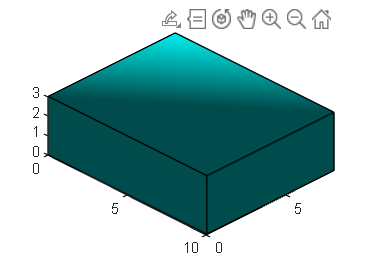

% Create a figure
fig = figure;

% Create axes for 3D plotting
ax = axes('Parent', fig);

% Define room dimensions
roomLength = 10;
roomWidth = 8;
roomHeight = 3;

% Define room corners
corners = [
    0, 0, 0;
    roomLength, 0, 0;
    roomLength, roomWidth, 0;
    0, roomWidth, 0;
    0, 0, roomHeight;
    roomLength, 0, roomHeight;
    roomLength, roomWidth, roomHeight;
    0, roomWidth, roomHeight
];

% Draw room using patch
room = patch('Vertices', corners, 'Faces', [1 2 6 5; 2 3 7 6; 3 4 8 7; 4 1 5 8; 1 2 3 4; 5 6 7 8], 'FaceColor', 'cyan', 'EdgeColor', 'k');

% Set axis limits
axis(ax, 'equal');
axis(ax, [0 roomLength 0 roomWidth 0 roomHeight]);

% Set view to first-person perspective
view(ax, 45, 30);

% Add camera toolbar for interactive control
cameratoolbar('SetMode', 'orbit');

% Customize lighting and appearance as needed
% Add lighting to the room
light('Position', [roomLength/2, roomWidth/2, roomHeight], 'Style', 'local');

% Set lighting properties
lighting(ax, 'phong');
material(ax, 'dull');

% ... (continue with the rest of your code)
% Add other furniture or details as desired
% Add a table
tableWidth = 3;
tableLength = 6;
tableHeight = 0.5;

tableVertices = [
    roomLength/2 - tableLength/2, roomWidth/2 - tableWidth/2, 0;
    roomLength/2 + tableLength/2, roomWidth/2 - tableWidth/2, 0;
    roomLength/2 + tableLength/2, roomWidth/2 + tableWidth/2, 0;
    roomLength/2 - tableLength/2, roomWidth/2 + tableWidth/2, 0;
    roomLength/2 - tableLength/2, roomWidth/2 - tableWidth/2, tableHeight;
    roomLength/2 + tableLength/2, roomWidth/2 - tableWidth/2, tableHeight;
    roomLength/2 + tableLength/2, roomWidth/2 + tableWidth/2, tableHeight;
    roomLength/2 - tableLength/2, roomWidth/2 + tableWidth/2, tableHeight
];

tableFaces = [1 2 3 4; 5 6 7 8; 1 2 6 5; 2 3 7 6; 3 4 8 7; 4 1 5 8];

table = patch('Vertices', tableVertices, 'Faces', tableFaces, 'FaceColor', 'white', 'EdgeColor', 'k');

% Add a chair
chairWidth = 1.5;
chairLength = 1.5;
chairHeight = 1.8;

chairVertices = [
    roomLength/3 - chairLength/2, roomWidth/3 - chairWidth/2, 0;
    roomLength/3 + chairLength/2, roomWidth/3 - chairWidth/2, 0;
    roomLength/3 + chairLength/2, roomWidth/3 + chairWidth/2, 0;
    roomLength/3 - chairLength/2, roomWidth/3 + chairWidth/2, 0;
    roomLength/3 - chairLength/2, roomWidth/3 - chairWidth/2, chairHeight;
    roomLength/3 + chairLength/2, roomWidth/3 - chairWidth/2, chairHeight;
    roomLength/3 + chairLength/2, roomWidth/3 + chairWidth/2, chairHeight;
    roomLength/3 - chairLength/2, roomWidth/3 + chairWidth/2, chairHeight
];

chairFaces = [1 2 3 4; 5 6 7 8; 1 2 6 5; 2 3 7 6; 3 4 8 7; 4 1 5 8];

chair = patch('Vertices', chairVertices, 'Faces', chairFaces, 'FaceColor', 'blue', 'EdgeColor', 'k');

% Adjust figure settings
set(fig, 'Name', 'Matlab Living Room', 'NumberTitle', 'off');